# Gràfics i Matlab

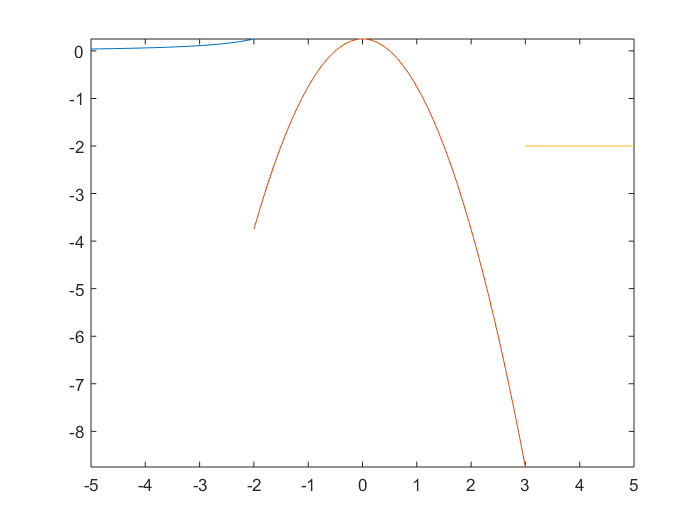


fplot(@(x)1./x.^2,[-5,-2])
hold on
fplot(@(x)1/4-x.^2,[-2,3])
fplot(@(x)-2.*ones(size(x)),[3,5]);
hold off

## SISTEMA D'EQUACIONS NO LINEALS

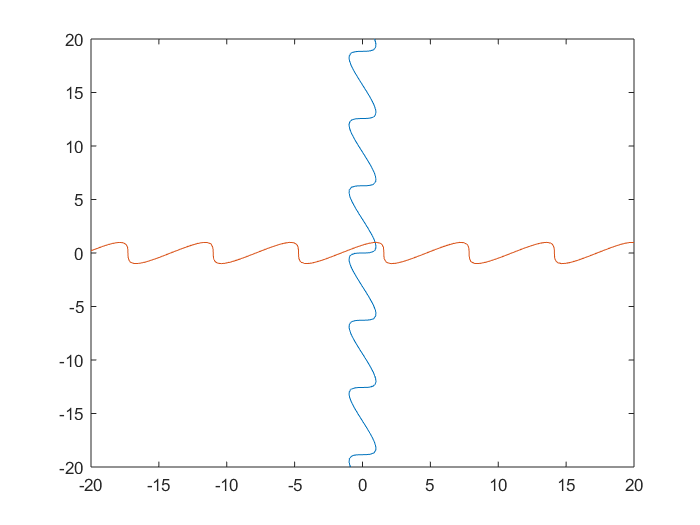

fimplicit(@(u,v)u-sin(u+v),[-20 20 -20 20])
hold on
fimplicit(@(u,v)v-cos(u-v),[-20 20 -20 20])
hold off

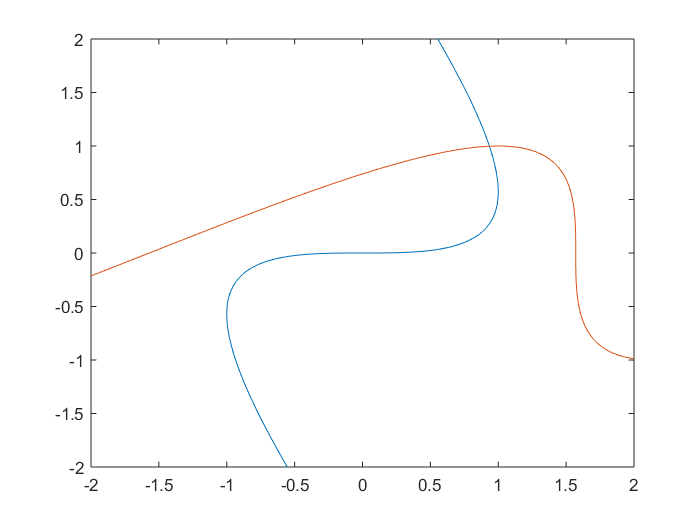

fimplicit(@(u,v)u-sin(u+v),[-2 2 -2 2]),grid
hold on
fimplicit(@(u,v)v-cos(u-v),[-2 2 -2 2]),grid
hold off

## MÈTODE ITERACIÓ SIMPLE 

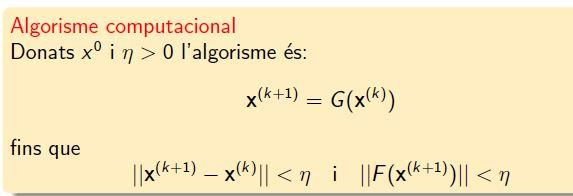

clearvars;
Z=[1 1]';
G = @(u,v)[sin(u+v);cos(u-v)]

G = function_handle with value:
    @(u,v)[sin(u+v);cos(u-v)]


G(1,1)

ans =     0.9093
    1.0000


for k=0:15
    Zold = Z;
    Z = G(Z(1),Z(2))
end

Z =     0.9093
    1.0000


Z =     0.9433
    0.9959


Z =     0.9329
    0.9986


Z =     0.9356
    0.9978


Z =     0.9349
    0.9981


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Z =     0.9351
    0.9980


Mètode iteratiu amb control iteracions, i toleràcies

clearvars;
Z=[1 1]';
F= @(u,v)[u-sin(u+v);v-cos(u-v)];
G = @(u,v)[sin(u+v);cos(u-v)];                          % Condició convergència FALTA
DG = @(u,v)[-cos(u+v) -cos(u+v); sin(u-v)  -sin(u-v)];  % Per convergència
control_apriori = norm(DG(Z(1),Z(2)),'inf')

control_apriori = 0.8323

if control_apriori >= 1
    error('mètode iteratiu divergent')
else
    k=0; 
    tolZ=1; 
    tolF=1;
    while ((tolZ > 1e-6 || tolF > 1e-6) &&  k<15)
        Zold = Z;
        Z = G(Z(1),Z(2));
        k=k+1
        tolZ = norm(Z-Zold,'inf')
        tolF = norm(F(Z(1),Z(2)),'inf')
    end
end

k = 1

tolZ = 0.0907

tolF = 0.0340

k = 2

tolZ = 0.0340

tolF = 0.0103

k = 3

tolZ = 0.0103

tolF = 0.0027

k = 4

tolZ = 0.0027

tolF = 6.8616e-04

k = 5

tolZ = 6.8616e-04

tolF = 1.6437e-04

k = 6

tolZ = 1.6437e-04

tolF = 3.8085e-05

k = 7

tolZ = 3.8085e-05

tolF = 8.5607e-06

k = 8

tolZ = 8.5607e-06

tolF = 1.8749e-06

k = 9

tolZ = 1.8749e-06

tolF = 4.0074e-07

k = 10

tolZ = 4.0074e-07

tolF = 8.3649e-08

## Mètode de NEWTON

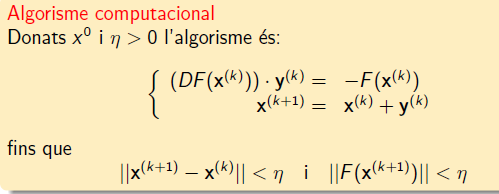

clearvars;
Z=[1 1]';

F= @(u,v)[u-sin(u+v);v-cos(u-v)];
DF = @(u,v)[1-cos(u+v) -cos(u+v); sin(u-v)  1-sin(u-v)];
k=0; 
tolZ=1; 
tolF=1;
while ((tolZ > 1e-6 || tolF > 1e-6) &&  k<15)
    Y = -DF(Z(1),Z(2))\F(Z(1),Z(2));
    Z = Z+Y;
    k=k+1
    tolZ = norm(Y,'inf')
    tolF = norm(F(Z(1),Z(2)),'inf')
end

k = 1

tolZ = 0.0640

tolF = 0.0021

k = 2

tolZ = 0.0020

tolF = 3.7834e-06

k = 3

tolZ = 2.6010e-06

tolF = 5.2036e-12

k = 4

tolZ = 3.3622e-12

tolF = 0

## 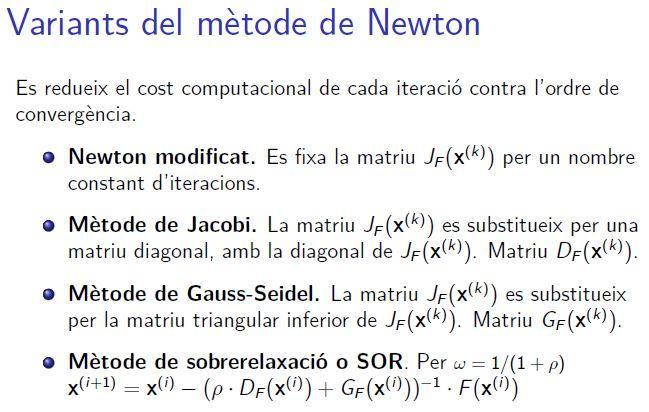

## Newton modificat

clearvars;
Z=[1 1]';

F= @(u,v)[u-sin(u+v);v-cos(u-v)];
DF = @(u,v)[1-cos(u+v) -cos(u+v); sin(u-v)  1-sin(u-v)];
k=0; 
tolZ=1; 
tolF=1;
JF = DF(Z(1),Z(2));
while ((tolZ > 1e-6 || tolF > 1e-6) &&  k<15)
    Y = -JF\F(Z(1),Z(2));
    Z = Z+Y;
    k=k+1
    tolZ = norm(Y,'inf')
    tolF = norm(F(Z(1),Z(2)),'inf')
end

k = 1

tolZ = 0.0640

tolF = 0.0021

k = 2

tolZ = 0.0021

tolF = 1.6761e-04

k = 3

tolZ = 1.4299e-04

tolF = 1.4245e-05

k = 4

tolZ = 1.4245e-05

tolF = 9.9726e-07

k = 5

tolZ = 9.9726e-07

tolF = 1.1578e-07

## Mètode de Jacobi

clearvars;
Z=[1 1]';

F= @(u,v)[u-sin(u+v);v-cos(u-v)]

F = function_handle with value:
    @(u,v)[u-sin(u+v);v-cos(u-v)]


DF = @(u,v)[1-cos(u+v) -cos(u+v); sin(u-v)  1-sin(u-v)]

DF = function_handle with value:
    @(u,v)[1-cos(u+v),-cos(u+v);sin(u-v),1-sin(u-v)]


k=0; 
tolZ=1; 
tolF=1;
while ((tolZ > 1e-6 || tolF > 1e-6) &&  k<15)
    JF = diag(diag(DF(Z(1),Z(2))));
    Y = -JF\F(Z(1),Z(2));
    Z = Z+Y;
    k=k+1
    tolZ = norm(Y,'inf')
    tolF = norm(F(Z(1),Z(2)),'inf')
end

k = 1

tolZ = 0.0640

tolF = 0.0021

k = 2

tolZ = 0.0019

tolF = 6.8302e-04

k = 3

tolZ = 5.0445e-04

tolF = 3.1843e-05

k = 4

tolZ = 2.9959e-05

tolF = 1.0618e-05

k = 5

tolZ = 7.8397e-06

tolF = 4.9306e-07

k = 6

tolZ = 4.6388e-07

tolF = 1.6442e-07

## Mètode de Gauss - Seidel

clearvars;
Z=[1 1]';

F= @(u,v)[u-sin(u+v);v-cos(u-v)];
DF = @(u,v)[1-cos(u+v) -cos(u+v); sin(u-v)  1-sin(u-v)];
k=0; 
tolZ=1; 
tolF=1;
while ((tolZ > 1e-6 || tolF > 1e-6) &&  k<15)
    JF = tril(DF(Z(1),Z(2)));
    Y = -JF\F(Z(1),Z(2));
    Z = Z+Y;
    k=k+1
    tolZ = norm(Y,'inf')
    tolF = norm(F(Z(1),Z(2)),'inf')
end

k = 1

tolZ = 0.0640

tolF = 0.0021

k = 2

tolZ = 0.0020

tolF = 7.1256e-04

k = 3

tolZ = 5.2629e-04

tolF = 1.1183e-05

k = 4

tolZ = 8.2566e-06

tolF = 2.1391e-07

k = 5

tolZ = 1.5793e-07

tolF = 3.3026e-09